% Load trajectory data and costmap
data = load('desired_trajectory.mat');
trajectory = data.trajectory;
time_vector = data.time_vector;
costmap = createParkingLotCostmap();

% Load global waypoints for visualization
global_data = load('GlobalRoutePlan.mat');
routePlan = global_data.routePlan;

% Configure LaTeX interpreter and plot styling - professional academic style
set(0, 'defaultTextInterpreter', 'latex');
set(0, 'defaultAxesTickLabelInterpreter', 'latex');
set(0, 'defaultLegendInterpreter', 'latex');

fontSize = 14;
titleSize = 16;
legendSize = 12;
lineWidth = 2;

% Define color palette
color_red = [0.8, 0.2, 0.2];      % Red for actual/errors
color_yellow = [0.8, 0.6, 0.2];   % Dark yellow for desired/reference
color_blue = [0.2, 0.3, 0.8];     % Dark blue for commands/analysis

% Create figure directory if it doesn't exist
if ~exist('figures', 'dir')
    mkdir('figures');
end

% Data preprocessing - Extract data from timeseries objects and ensure proper dimensions
fprintf('Preprocessing timeseries data...\n');

Preprocessing timeseries data...



% Extract all timeseries data
[time_actual_state, data_actual_state] = extractTimeseriesData(out_actual_state);
[time_actual_statedot, data_actual_statedot] = extractTimeseriesData(out_actual_statedot);
[time_v_cmd, data_v_cmd] = extractTimeseriesData(out_v_cmd);
[time_phi_cmd, data_phi_cmd] = extractTimeseriesData(out_phi_cmd);
[time_x_error, data_x_error] = extractTimeseriesData(out_x_error);
[time_y_error, data_y_error] = extractTimeseriesData(out_y_error);
[time_theta_error, data_theta_error] = extractTimeseriesData(out_theta_error);
[time_x_dot_error, data_x_dot_error] = extractTimeseriesData(out_x_dot_error);
[time_y_dot_error, data_y_dot_error] = extractTimeseriesData(out_y_dot_error);
[time_theta_dot_error, data_theta_dot_error] = extractTimeseriesData(out_theta_dot_error);

% Check if data was extracted correctly
fprintf('Data dimensions check:\n');

Data dimensions check:


fprintf('  Actual state: %d x %d\n', size(data_actual_state));

  Actual state: 2001 x 3


fprintf('  Actual state time: %d\n', length(time_actual_state));

  Actual state time: 2001


fprintf('  Desired trajectory length: %d\n', length(trajectory.xd));

  Desired trajectory length: 2001



% Determine actual simulation duration
actual_sim_duration = time_actual_state(end);
if isfield(trajectory, 'actual_duration')
    trajectory_duration = trajectory.actual_duration;
else
    trajectory_duration = actual_sim_duration;
end

fprintf('  Actual simulation duration: %.2f s\n', actual_sim_duration);

  Actual simulation duration: 200.00 s


fprintf('  Trajectory completion time: %.2f s\n', trajectory_duration);

  Trajectory completion time: 105.18 s



%% 1. TRAJECTORY TRACKING PERFORMANCE WITH MAP VISUALIZATION
fprintf('Generating trajectory tracking visualization...\n');

Generating trajectory tracking visualization...


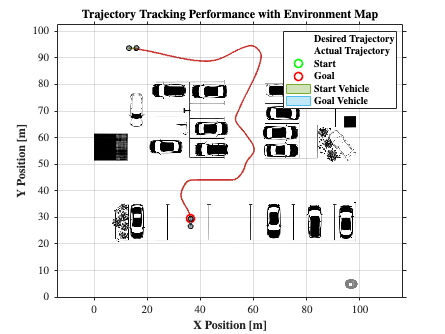


% Create a new figure for trajectory tracking
figure('Name', 'Trajectory Tracking', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);

% Plot cost map
plot(costmap, 'Inflation', 'off');
hold on;

% Plot desired trajectory
plot(trajectory.xd, trajectory.yd, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Trajectory}');

% Plot actual trajectory
if ~isempty(data_actual_state)
    plot(data_actual_state(:,1), data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Trajectory}');
end

% Plot start and goal positions
initialPose = routePlan{1, 'StartPose'};
finalGoal = routePlan{end, 'EndPose'};
plot(initialPose(1), initialPose(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', '\textbf{Start}');
plot(finalGoal(1), finalGoal(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', '\textbf{Goal}');

% Add vehicle representation at key points (if function exists)
if exist('PlotBicycle', 'file')
    PlotBicycle(initialPose, costmap.CollisionChecker.VehicleDimensions, 'DisplayName', '\textbf{Start Vehicle}');
    PlotBicycle(finalGoal, costmap.CollisionChecker.VehicleDimensions, 'DisplayName', '\textbf{Goal Vehicle}');
end

% Set labels, title and legend with LaTeX formatting
xlabel('\textbf{X Position [m]}', 'FontSize', fontSize);
ylabel('\textbf{Y Position [m]}', 'FontSize', fontSize);
title('\textbf{Trajectory Tracking Performance with Environment Map}', 'FontSize', titleSize);

% Set axis limits and legend position
legend('Location', 'northeast', 'FontSize', legendSize);

% Final axis settings
axis equal;
grid on;
hold off;
set(gca, 'FontSize', fontSize);

% Save figure
saveas(gcf, 'figures/trajectory_tracking_centered.eps', 'epsc');


%% 2. STATE VARIABLES TRACKING COMPARISON
fprintf('Generating state variables comparison...\n');

Generating state variables comparison...


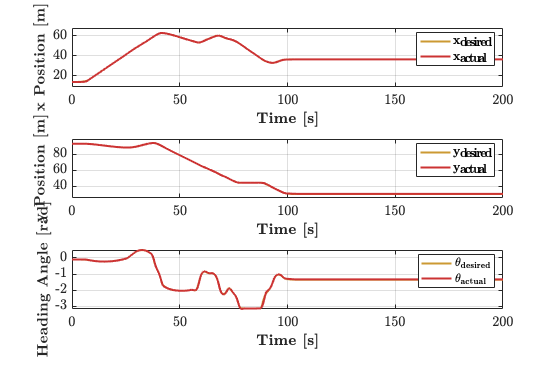

figure('Position', [150, 150, 1200, 800]);

% Determine common time range
t_end = min(actual_sim_duration, time_vector(end));

% X position tracking
subplot(3, 1, 1);
% Plot only up to actual simulation time
valid_idx = time_vector <= t_end;
plot(time_vector(valid_idx), trajectory.xd(valid_idx), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{desired}}$');
hold on;
if ~isempty(data_actual_state)
    plot(time_actual_state, data_actual_state(:,1), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{actual}}$');
end
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{x Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
ylim([min([trajectory.xd(valid_idx); data_actual_state(:,1)])-5, ...
      max([trajectory.xd(valid_idx); data_actual_state(:,1)])+5]);
xlim([0, t_end]);
grid on;
set(gca, 'FontSize', fontSize);

% Y position tracking
subplot(3, 1, 2);
plot(time_vector(valid_idx), trajectory.yd(valid_idx), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{desired}}$');
hold on;
if ~isempty(data_actual_state)
    plot(time_actual_state, data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{actual}}$');
end
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{y Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
ylim([min([trajectory.yd(valid_idx); data_actual_state(:,2)])-5, ...
      max([trajectory.yd(valid_idx); data_actual_state(:,2)])+5]);
xlim([0, t_end]);
grid on;
set(gca, 'FontSize', fontSize);

% Heading tracking
subplot(3, 1, 3);
plot(time_vector(valid_idx), trajectory.thetad(valid_idx), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{\theta_{desired}}$');
hold on;
if ~isempty(data_actual_state) && size(data_actual_state, 2) >= 3
    plot(time_actual_state, data_actual_state(:,3), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{\theta_{actual}}$');
end
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading Angle [rad]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, t_end]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/state_variables_tracking.eps', 'epsc');


%% 3. TRACKING ERRORS ANALYSIS
fprintf('Generating tracking errors analysis...\n');

Generating tracking errors analysis...


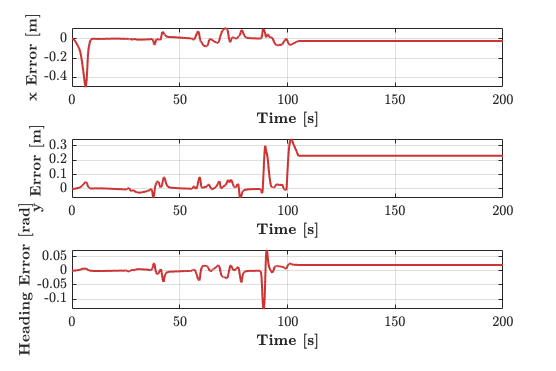


% Interpolate the reference trajectory at simulation times
xd_interp = interp1(time_vector, trajectory.xd, time_actual_state, 'linear', 'extrap');
yd_interp = interp1(time_vector, trajectory.yd, time_actual_state, 'linear', 'extrap');
thetad_interp = interp1(time_vector, trajectory.thetad, time_actual_state, 'linear', 'extrap');

% Calculate synchronized errors
x_error_sync = data_actual_state(:,1) - xd_interp;
y_error_sync = data_actual_state(:,2) - yd_interp;
theta_error_sync = wrapToPi(data_actual_state(:,3) - thetad_interp);

% Calculate Euclidean error
euclidean_error_sync = sqrt(x_error_sync.^2 + y_error_sync.^2);

figure('Position', [100, 100, 1200, 800]);

% Plot X error
subplot(3, 1, 1);
plot(time_actual_state, x_error_sync, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{x Error [m]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_x_error = mean(abs(x_error_sync));
max_x_error = max(abs(x_error_sync));
text(0.02, 150, sprintf('\\textbf{Mean: %.3f m, Max: %.3f m}', mean_x_error, max_x_error),...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Plot Y error
subplot(3, 1, 2);
plot(time_actual_state, y_error_sync, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{y Error [m]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_y_error = mean(abs(y_error_sync));
max_y_error = max(abs(y_error_sync));
text(0.02,150,sprintf('\\textbf{Mean: %.3f m, Max: %.3f m}', mean_y_error, max_y_error), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Plot theta error
subplot(3, 1, 3);
plot(time_actual_state, theta_error_sync, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading Error [rad]}', 'FontSize', fontSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_theta_error = mean(abs(theta_error_sync));
max_theta_error = max(abs(theta_error_sync));
text(0.02,150, sprintf('\\textbf{Mean: %.3f rad, Max: %.3f rad}', mean_theta_error, max_theta_error), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

saveas(gcf, 'figures/tracking_errors_analysis.eps', 'epsc');


%% 4. CONTROL COMMANDS ANALYSIS
fprintf('Generating control commands analysis...\n');

Generating control commands analysis...


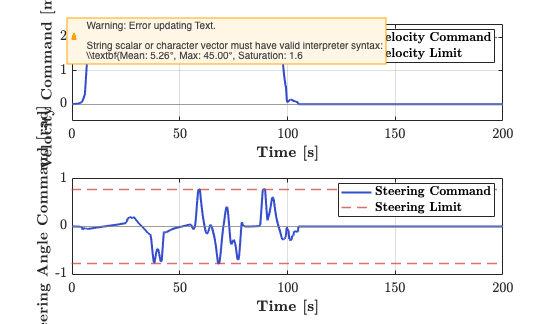

figure('Position', [250, 250, 1200, 700]);

% Velocity command
subplot(2, 1, 1);
v_max = 2; % Adjust according to your actual limits

% Plot velocity command
plot(time_v_cmd, data_v_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Velocity Command}');
hold on;

% Plot limits
yline(v_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'DisplayName', '\textbf{Velocity Limit}');
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');

xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity Command [m/s]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
ylim([-0.5, v_max*1.2]);
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);

% Statistics
mean_v_cmd = mean(data_v_cmd);
max_v_cmd = max(abs(data_v_cmd));
text(0.02,150, sprintf('\\textbf{Mean: %.2f m/s, Max: %.2f m/s}', mean_v_cmd, max_v_cmd), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Steering command
subplot(2, 1, 2);
phi_max = pi/4; % 30 degrees

% Plot steering command
plot(time_phi_cmd, data_phi_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Steering Command}');
hold on;

% Plot limits
yline(phi_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'DisplayName', '\textbf{Steering Limit}');
yline(-phi_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');

xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Steering Angle Command [rad]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
ylim([-phi_max*1.3, phi_max*1.3]);
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);

% Statistics
mean_phi_cmd = mean(abs(data_phi_cmd));
max_phi_cmd = max(abs(data_phi_cmd));
saturation_percentage = sum(abs(data_phi_cmd) > phi_max*0.95) / length(data_phi_cmd) * 100;
text(0.02,150, sprintf('\\textbf{Mean: %.2f°, Max: %.2f°, Saturation: %.1f%%}', ...
     mean_phi_cmd*180/pi, max_phi_cmd*180/pi, saturation_percentage), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

saveas(gcf, 'figures/control_commands_analysis.eps', 'epsc');


%% 5. VELOCITY TRACKING AND ERRORS
fprintf('Generating velocity tracking analysis...\n');

Generating velocity tracking analysis...


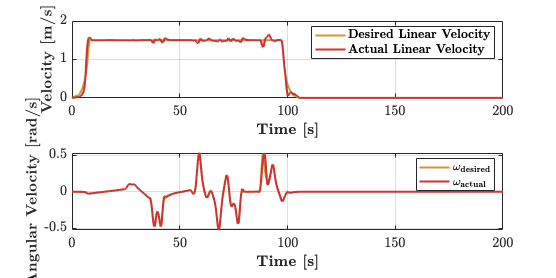


% Calculate velocities
desired_velocity = sqrt(trajectory.xd_dot.^2 + trajectory.yd_dot.^2);
actual_velocity = sqrt(data_actual_statedot(:,1).^2 + data_actual_statedot(:,2).^2);

% Apply smoothing if data is long enough
smoothing_span = 21;
if length(desired_velocity) > smoothing_span
    desired_velocity_smooth = smooth(desired_velocity, smoothing_span, 'sgolay', 2);
else
    desired_velocity_smooth = desired_velocity;
end

if length(actual_velocity) > smoothing_span
    actual_velocity_smooth = smooth(actual_velocity, smoothing_span, 'sgolay', 2);
else
    actual_velocity_smooth = actual_velocity;
end

% FIRST FIGURE: Velocity Tracking
figure('Position', [300, 300, 1200, 600]);

% Linear velocity tracking
subplot(2, 1, 1);
valid_idx = time_vector <= actual_sim_duration;
plot(time_vector(valid_idx), desired_velocity_smooth(valid_idx), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Linear Velocity}');
hold on;
plot(time_actual_statedot, actual_velocity_smooth, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Linear Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity [m/s]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Angular velocity tracking
subplot(2, 1, 2);
if length(trajectory.thetad_dot) > smoothing_span
    theta_dot_desired_smooth = smooth(trajectory.thetad_dot, smoothing_span, 'sgolay', 2);
else
    theta_dot_desired_smooth = trajectory.thetad_dot;
end

if length(data_actual_statedot(:,3)) > smoothing_span
    theta_dot_actual_smooth = smooth(data_actual_statedot(:,3), smoothing_span, 'sgolay', 2);
else
    theta_dot_actual_smooth = data_actual_statedot(:,3);
end

plot(time_vector(valid_idx), theta_dot_desired_smooth(valid_idx), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{$\mathbf{\omega_{desired}}$}');
hold on;
plot(time_actual_statedot, theta_dot_actual_smooth, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{$\mathbf{\omega_{actual}}$}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity [rad/s]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/velocity_tracking_analysis.eps', 'epsc');


%% 6. EUCLIDEAN ERROR OVER TIME
fprintf('Generating Euclidean error plot...\n');

Generating Euclidean error plot...


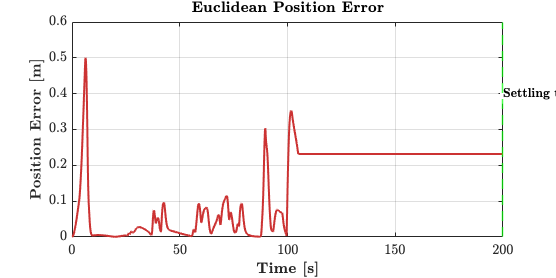

figure('Position', [350, 350, 800, 400]);

plot(time_actual_state, euclidean_error_sync, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
title('\textbf{Euclidean Position Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Add settling time marker if applicable
settling_threshold = 0.5;
settling_idx = find(euclidean_error_sync < settling_threshold, 1, 'last');
if ~isempty(settling_idx)
    hold on;
    xline(time_actual_state(settling_idx), '--g', 'LineWidth', 1.5);
    text(time_actual_state(settling_idx), max(euclidean_error_sync)*0.8, ...
         sprintf('\\textbf{Settling time: %.1f s}', time_actual_state(settling_idx)), ...
         'FontSize', fontSize-2, 'BackgroundColor', 'white');
end

saveas(gcf, 'figures/euclidean_error.eps', 'epsc');


%% 7. STATISTICAL ANALYSIS
fprintf('Generating statistical analysis...\n');

Generating statistical analysis...


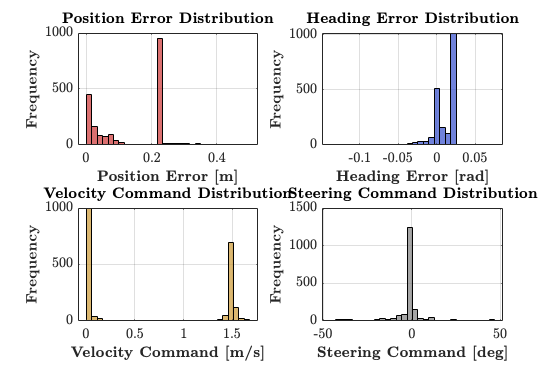

figure('Position', [400, 400, 1200, 800]);

% Position error distribution
subplot(2, 2, 1);
histogram(euclidean_error_sync, 30, 'FaceColor', color_red, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Position Error Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Heading error distribution
subplot(2, 2, 2);
histogram(theta_error_sync, 30, 'FaceColor', color_blue, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Heading Error [rad]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Heading Error Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Control effort distribution
subplot(2, 2, 3);
histogram(data_v_cmd, 30, 'FaceColor', color_yellow, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Velocity Command [m/s]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Velocity Command Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Steering effort distribution
subplot(2, 2, 4);
histogram(data_phi_cmd*180/pi, 30, 'FaceColor', [0.5 0.5 0.5], 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Steering Command [deg]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Steering Command Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/statistical_analysis.eps', 'epsc');



%% 9. VELOCITY ERRORS ANALYSIS
fprintf('Generating velocity errors analysis...\n');

Generating velocity errors analysis...


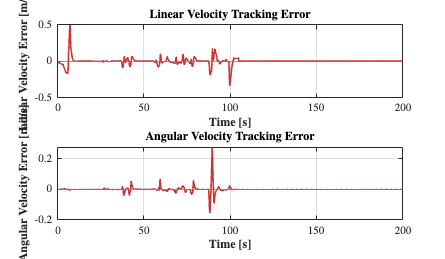


% Interpolate desired velocities at actual simulation times for correct error calculation
desired_velocity_interp = interp1(time_vector, desired_velocity, time_actual_statedot, 'linear', 'extrap');
desired_ang_velocity_interp = interp1(time_vector, trajectory.thetad_dot, time_actual_statedot, 'linear', 'extrap');

% Calculate synchronized errors
lin_vel_error = actual_velocity - desired_velocity_interp;
ang_vel_error = data_actual_statedot(:,3) - desired_ang_velocity_interp;

% Create the figure
figure('Name', 'Velocity Errors Analysis', 'Position', [200, 200, 1200, 700]);

% Subplot 1: Linear Velocity Error
subplot(2, 1, 1);
plot(time_actual_statedot, lin_vel_error, 'Color', color_red, 'LineWidth', lineWidth);
hold on;
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Linear Velocity Error [m/s]}', 'FontSize', fontSize);
title('\textbf{Linear Velocity Tracking Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_err = mean(abs(lin_vel_error));
max_err = max(abs(lin_vel_error));
text(0.02, 150, sprintf('\\textbf{Mean Abs: %.3f m/s, Max Abs: %.3f m/s}', mean_err, max_err), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Subplot 2: Angular Velocity Error
subplot(2, 1, 2);
plot(time_actual_statedot, ang_vel_error, 'Color', color_red, 'LineWidth', lineWidth);
hold on;
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity Error [rad/s]}', 'FontSize', fontSize);
title('\textbf{Angular Velocity Tracking Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_err_ang = mean(abs(ang_vel_error));
max_err_ang = max(abs(ang_vel_error));
text(0.02, 150, sprintf('\\textbf{Mean Abs: %.3f rad/s, Max Abs: %.3f rad/s}', mean_err_ang, max_err_ang), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Save the figure
saveas(gcf, 'figures/velocity_errors_analysis.eps', 'epsc');



%% 10. CONTROLLER PERFORMANCE COMPARISON DASHBOARD
fprintf('Generating controller comparison dashboard...\n');

Generating controller comparison dashboard...


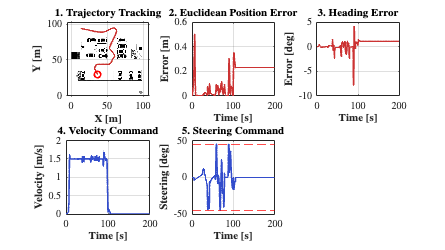


figure('Name', 'Controller Performance Dashboard', 'Position', [100, 100, 1600, 900]);

% --- 1. Trajectory Tracking on Map ---
subplot(2, 3, 1);
plot(costmap, 'Inflation', 'off');
hold on;
plot(trajectory.xd, trajectory.yd, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', 'Desired');
plot(data_actual_state(:,1), data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', 'Actual');
plot(routePlan{1, 'StartPose'}(1), routePlan{1, 'StartPose'}(2), 'go', 'MarkerSize', 8, 'LineWidth', 2);
plot(routePlan{end, 'EndPose'}(1), routePlan{end, 'EndPose'}(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('\textbf{X [m]}'); ylabel('\textbf{Y [m]}');
title('\textbf{1. Trajectory Tracking}');
axis equal; grid on;
set(gca, 'FontSize', fontSize-2);

% --- 2. Euclidean Position Error ---
subplot(2, 3, 2);
plot(time_actual_state, euclidean_error_sync, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Error [m]}');
title('\textbf{2. Euclidean Position Error}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 3. Heading Error ---
subplot(2, 3, 3);
plot(time_actual_state, theta_error_sync * 180/pi, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Error [deg]}');
title('\textbf{3. Heading Error}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 4. Velocity Command ---
subplot(2, 3, 4);
plot(time_v_cmd, data_v_cmd, 'Color', color_blue, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Velocity [m/s]}');
title('\textbf{4. Velocity Command}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 5. Steering Command ---
subplot(2, 3, 5);
plot(time_phi_cmd, data_phi_cmd * 180/pi, 'Color', color_blue, 'LineWidth', lineWidth);
hold on;
yline(phi_max*180/pi, '--r', 'LineWidth', 1);
yline(-phi_max*180/pi, '--r', 'LineWidth', 1);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Steering [deg]}');
title('\textbf{5. Steering Command}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);


% --- 6. Key Performance Indicators (KPIs) ---
% subplot(2, 3, 6);
% % Calculate KPIs
% kpi_max_pos_err = max(euclidean_error_sync);
% kpi_rms_pos_err = rms(euclidean_error_sync);
% settling_time_val = NaN;
% settling_idx = find(euclidean_error_sync(1:end-10) < 0.2, 1); % Threshold 20cm
% if ~isempty(settling_idx)
%     settling_time_val = time_actual_state(settling_idx);
% end
% kpi_final_heading_err = abs(theta_error_sync(end)) * 180/pi;
% kpi_saturation = saturation_percentage;
% 
% % Create bar chart
% kpi_names = categorical({'Max Pos Err [m]', 'RMS Pos Err [m]', 'Settling Time [s]', 'Final Head Err [deg]', 'Saturation [\%]'});
% kpi_names = reordercats(kpi_names,{'Max Pos Err [m]', 'RMS Pos Err [m]', 'Settling Time [s]', 'Final Head Err [deg]', 'Saturation [\%]'});
% kpi_values = [kpi_max_pos_err, kpi_rms_pos_err, settling_time_val, kpi_final_heading_err, kpi_saturation];
% bar_plot = bar(kpi_names, kpi_values, 'FaceColor', color_blue);
% title('\textbf{6. Key Performance Indicators}');
% ylabel('\textbf{Value}');
% grid on;
% set(gca, 'FontSize', fontSize-2);
% % Add text labels to bars
% xtips = bar_plot.XEndPoints;
% ytips = bar_plot.YEndPoints;
% labels = string(round(bar_plot.YData, 2));
% text(xtips, ytips, labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom', 'FontSize', fontSize-2);
% ylim([0, max(ytips)*1.15]);
% 
% 
% % Save the figure
% saveas(gcf, 'figures/controller_dashboard.eps', 'epsc');


%% 10. KPI SUMMARY PLOT - MODIFICA 6: New figure without Settling Time
fprintf('Generating KPI summary plot...\n');

Generating KPI summary plot...


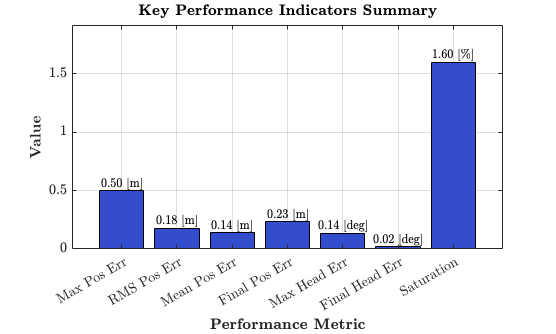


% Calculate KPIs
kpi_max_pos_err = max(euclidean_error_sync);
kpi_rms_pos_err = rms(euclidean_error_sync);
kpi_mean_pos_err = mean(euclidean_error_sync);
kpi_final_pos_err = euclidean_error_sync(end);
kpi_max_heading_err = max(abs(theta_error_sync));
kpi_final_heading_err = abs(theta_error_sync(end));
kpi_saturation = saturation_percentage;

figure('Position', [550, 550, 1000, 600]);

% Create KPI names and values
kpi_names = categorical({'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                        'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_names = reordercats(kpi_names, {'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                                    'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_values = [kpi_max_pos_err, kpi_rms_pos_err, kpi_mean_pos_err, kpi_final_pos_err, ...
              kpi_max_heading_err, kpi_final_heading_err, kpi_saturation];
kpi_units = {'[m]', '[m]', '[m]', '[m]', '[deg]', '[deg]', '[\%]'};

% Create bar plot
bar_plot = bar(kpi_names, kpi_values, 'FaceColor', color_blue);

% Add value labels on bars
xtips = bar_plot.XEndPoints;
ytips = bar_plot.YEndPoints;
for i = 1:length(ytips)
    text(xtips(i), ytips(i), sprintf('%.2f %s', kpi_values(i), kpi_units{i}), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', fontSize-2, 'FontWeight', 'bold');
end

xlabel('\textbf{Performance Metric}', 'FontSize', fontSize);
ylabel('\textbf{Value}', 'FontSize', fontSize);
title('\textbf{Key Performance Indicators Summary}', 'FontSize', titleSize);
grid on;
ylim([0, max(ytips)*1.2]);
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/controller_dashboard.eps', 'epsc');

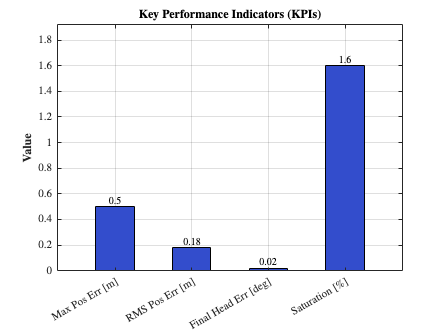


figure('Name', 'Key Performance Indicators', 'Position', [300, 300, 800, 600]);

% Create categorical array for bar labels
kpi_names = categorical({'Max Pos Err [m]', 'RMS Pos Err [m]', 'Final Head Err [deg]', 'Saturation [\%]'});
% Ensure order is preserved
kpi_names = reordercats(kpi_names,{'Max Pos Err [m]', 'RMS Pos Err [m]', 'Final Head Err [deg]', 'Saturation [\%]'});
kpi_values = [kpi_max_pos_err, kpi_rms_pos_err, kpi_final_heading_err, kpi_saturation];

% Create bar chart
bar_plot = bar(kpi_names, kpi_values, 0.5, 'FaceColor', color_blue, 'EdgeColor', 'black');

% Set title and labels
title('\textbf{Key Performance Indicators (KPIs)}', 'FontSize', titleSize);
ylabel('\textbf{Value}', 'FontSize', fontSize);
grid on;
set(gca, 'FontSize', fontSize);

% Add text labels on top of each bar for clarity
xtips = bar_plot.XEndPoints;
ytips = bar_plot.YEndPoints;
labels = string(round(bar_plot.YData, 2));
text(xtips, ytips, labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom', 'FontSize', fontSize-2, 'FontWeight', 'bold');

% Adjust y-axis limit to give space for labels
ylim([0, max(ytips)*1.2]); 

% Save the figure
saveas(gcf, 'figures/kpi_summary_plot.eps', 'epsc')





%% 8. PERFORMANCE SUMMARY
fprintf('\n=== CONTROLLER PERFORMANCE SUMMARY ===\n');


=== CONTROLLER PERFORMANCE SUMMARY ===


fprintf('Position Tracking:\n');

Position Tracking:


fprintf('  Mean Error: %.3f m\n', mean(euclidean_error_sync));

  Mean Error: 0.141 m


fprintf('  Max Error: %.3f m\n', max(euclidean_error_sync));

  Max Error: 0.500 m


fprintf('  RMS Error: %.3f m\n', sqrt(mean(euclidean_error_sync.^2)));

  RMS Error: 0.178 m


fprintf('  Final Error: %.3f m\n', euclidean_error_sync(end));

  Final Error: 0.232 m


fprintf('\nHeading Tracking:\n');


Heading Tracking:


fprintf('  Mean Error: %.3f rad (%.1f°)\n', mean(abs(theta_error_sync)), mean(abs(theta_error_sync))*180/pi);

  Mean Error: 0.014 rad (0.8°)


fprintf('  Max Error: %.3f rad (%.1f°)\n', max(abs(theta_error_sync)), max(abs(theta_error_sync))*180/pi);

  Max Error: 0.135 rad (7.7°)


fprintf('  Final Error: %.3f rad (%.1f°)\n', abs(theta_error_sync(end)), abs(theta_error_sync(end))*180/pi);

  Final Error: 0.020 rad (1.2°)


fprintf('\nControl Commands:\n');


Control Commands:


fprintf('  Mean Velocity: %.2f m/s\n', mean(data_v_cmd));

  Mean Velocity: 0.70 m/s


fprintf('  Max Steering: %.3f rad (%.1f°)\n', max(abs(data_phi_cmd)), max(abs(data_phi_cmd))*180/pi);

  Max Steering: 0.785 rad (45.0°)


fprintf('  Steering Saturation: %.1f%%\n', saturation_percentage);

  Steering Saturation: 1.6%


fprintf('\nTiming:\n');


Timing:


fprintf('  Simulation Time: %.1f s\n', actual_sim_duration);

  Simulation Time: 200.0 s


fprintf('  Trajectory Duration: %.1f s\n', trajectory_duration);

  Trajectory Duration: 105.2 s



settling_time_idx = find(euclidean_error_sync < settling_threshold, 1);
if ~isempty(settling_time_idx)
    fprintf('  Settling Time (< %.1f m): %.1f s\n', settling_threshold, time_actual_state(settling_time_idx));
else
    fprintf('  Settling Time: Not achieved\n');
end

  Settling Time (< 0.5 m): 0.0 s


fprintf('======================================\n');

## Helper Functions

function [time_data, signal_data] = extractTimeseriesData(ts_obj)
    if isa(ts_obj, 'timeseries')
        time_data = ts_obj.Time;
        signal_data = squeeze(ts_obj.Data); % Remove singleton dimensions
        
        % Ensure proper orientation
        if size(signal_data, 1) == 1 && size(signal_data, 2) > 1
            signal_data = signal_data'; % Transpose to column vector
        end
        
        % Remove any NaN or Inf values
        valid_idx = all(isfinite(signal_data), 2);
        time_data = time_data(valid_idx);
        signal_data = signal_data(valid_idx, :);
    else
        error('Input must be a timeseries object');
    end
end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end